data=load("data.mat");

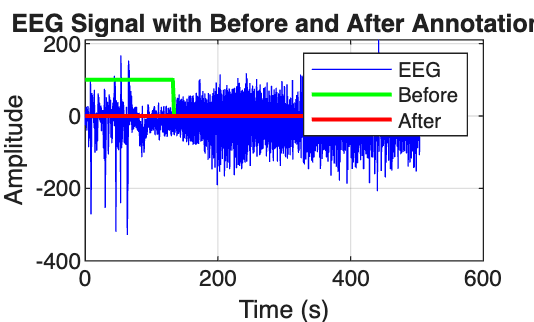

%% plots of EEG before and after

figure;
plot(data.eeg_time, data.eeg_ch, 'b', 'LineWidth',0.5); 
hold on;

scale_factor = 100;
plot(data.annot_time, data.before * scale_factor, 'g', 'LineWidth', 1.5); 
plot(data.annot_time, data.after * scale_factor, 'r', 'LineWidth', 1.5);  

xlabel('Time (s)');
ylabel('Amplitude');
title('EEG Signal with Before and After Annotations');
legend('EEG', 'Before', 'After');

grid on;

%% Sampling frequency

% time differences
dt = diff(data.eeg_time);  % dt is a vector of differences

% sampling interval
T_avg = mean(dt);  

fs = round(1 / T_avg);
fprintf("Sampling frequency: %.0f Hz\n", fs);

Sampling frequency: 128 Hz


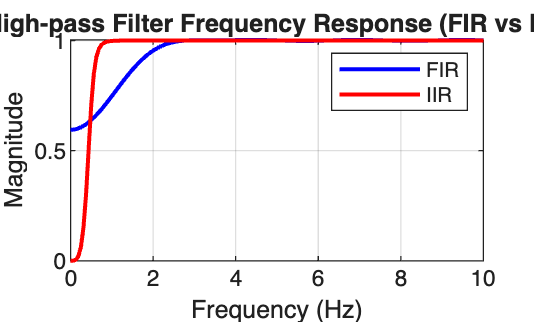

%% Highpass filter

fc = 0.5;       

N_fir = 100; 
b_fir = fir1(N_fir, fc/(fs/2), 'high');  
a_fir = 1;     

N_iir = 4;  
[b_iir, a_iir] = butter(N_iir, fc/(fs/2), 'high'); 

% FIR 
[H_fir, f_fir] = freqz(b_fir, a_fir, 1024, fs);

figure;
plot(f_fir, abs(H_fir), 'b', 'LineWidth', 1.5); hold on;

% IIR 
[H_iir, f_iir] = freqz(b_iir, a_iir, 1024, fs);
plot(f_iir, abs(H_iir), 'r', 'LineWidth', 1.5);

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('High-pass Filter Frequency Response (FIR vs IIR)');
legend('FIR', 'IIR');
grid on;
xlim([0 10]);  

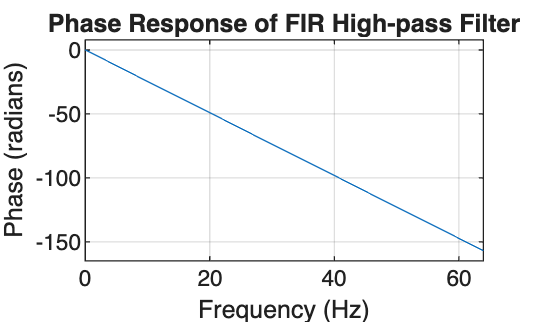


eeg_fir = filtfilt(b_fir, a_fir, data.eeg_ch);
eeg_iir = filtfilt(b_iir, a_iir, data.eeg_ch);


% FIR phase response check
figure;
phasez(b_fir, a_fir, 1024, fs);
title('Phase Response of FIR High-pass Filter');
grid on;


% zero-phase FIR 
eeg_f = filtfilt(b_fir, a_fir, data.eeg_ch);


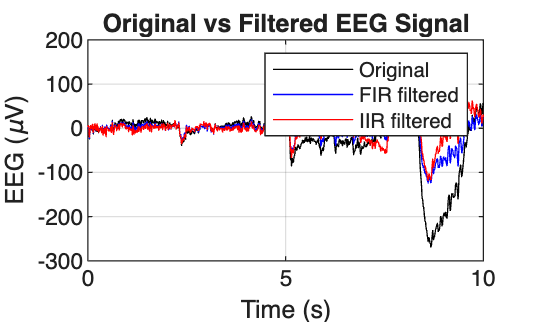

%% Original vs filtered EEG signal

t = data.eeg_time;
figure;
plot(t, data.eeg_ch, 'k', 'DisplayName','Original'); hold on;
plot(t, eeg_fir, 'b', 'DisplayName','FIR filtered');
plot(t, eeg_iir, 'r', 'DisplayName','IIR filtered');
xlim([0 10]);
xlabel('Time (s)');
ylabel('EEG (\muV)');
title('Original vs Filtered EEG Signal')
legend;
grid on;

%% Spectral entropy

[H, H_t] = entropy_eeg(eeg_f, fs);  % H: spectral entropy (0–1), H_t: time points

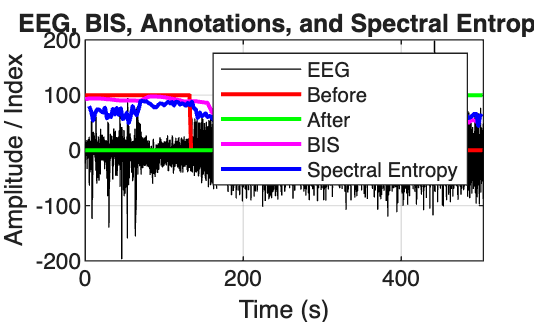

%% EEG, annotations, BIS, and spectral entropy

figure;
plot(data.eeg_time, eeg_f, 'k', 'DisplayName','Filtered EEG'); hold on;

plot(data.annot_time, data.before*scale_factor, 'r', 'LineWidth',1.5);
plot(data.annot_time, data.after*scale_factor, 'g', 'LineWidth',1.5);

plot(data.bis_time, data.bis_ch, 'm', 'LineWidth',1.5);

plot(H_t, H*100, 'b', 'LineWidth',1.5);  

xlabel('Time (s)');
ylabel('Amplitude / Index');
title('EEG, BIS, Annotations, and Spectral Entropy');
legend('EEG','Before','After','BIS','Spectral Entropy');
grid on;
xlim([0 data.eeg_time(end)]);

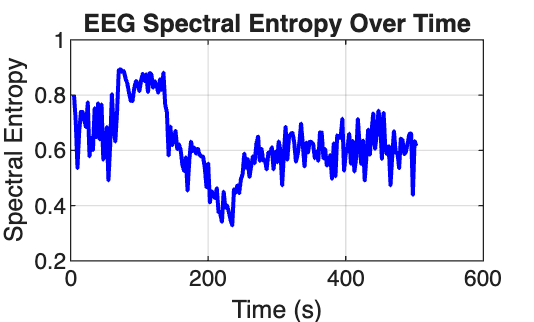


min(H);
max(H);

[H, H_t] = entropy_eeg(eeg_f, fs);
figure;
plot(H_t, H, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Spectral Entropy');
title('EEG Spectral Entropy Over Time');
grid on;

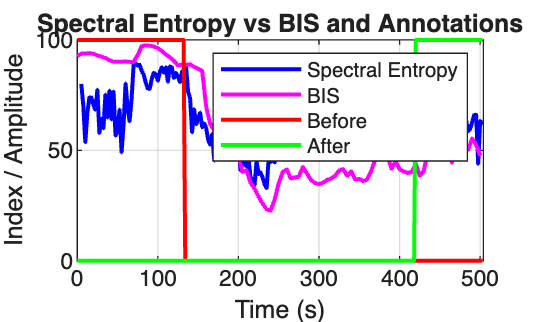

% Spectral Entropy vs BIS and annotations
H_scaled = H * 100;
figure;
plot(H_t, H_scaled, 'b', 'LineWidth', 1.5); hold on;      
plot(data.bis_time, data.bis_ch, 'm', 'LineWidth', 1.5);

scale_factor = 100;
plot(data.annot_time, data.before*scale_factor, 'r', 'LineWidth',1.5); 
plot(data.annot_time, data.after*scale_factor, 'g', 'LineWidth',1.5);  

xlabel('Time (s)');
ylabel('Index / Amplitude');
title('Spectral Entropy vs BIS and Annotations');
legend('Spectral Entropy','BIS','Before','After');
grid on;
xlim([0 data.eeg_time(end)]);